# Effects of First Year Class Ending Time on Dining Hall Queue during Lunchtimes at Olin

**Wren Yockey and Smaran Vallabhaneni**

## The Question

*How does the end time of the morning classes for first years affect the wait time in the Olin Dining Hall during lunchtime?*

**Modeling Question and Categorization:**

Our modelling question is how does the end time of morning first year classes affect the wait time in the Olin dining hall. We decided that this is a specific question, as we are examining a very specific phenomenon localized to a small point in time at Olin. Our question is also more rhetorical, as we are examining the general, qualitative ways in which a change affects a queue. We do not have any specific values we are trying to attain with a specific change.

**Importance / Interest:**

This question is important as it is very applicable to most Olin students, especially in the fall semester where first years tend to have similar class times that get out right at noon. If we can understand how altering the class end times affects the dining hall queue structure, we can improve the service rate of the Olin dining hall by offsetting when classes end. This will reduce the stress on dining hall staff, and improve student’s experience with getting food and using the dining hall in general.

**Background Information and References:**

Our background research showed a few different ways that queues have been modelled in the past. Queue theory generally is used for more simple systems, where a determined arrival rate and service rate are used to calculate and optimize the time it takes someone to move through the system (Kyoung Won Cho et al., 2017). This would not fit conventionally to our model, as we have a complex system of individuals, which don’t necessarily move linearly through the queue. Additionally, most conventional queue mappings have a theoretically infinite calling population, and are bottlenecked by arrival rate, which is modelled as a Poisson distribution (Abhishek Yadav , Dr. Nagendra Sohani, 2019). At the Olin dining hall, there is actually a quite small calling population, and we are only modelling up to 100 people arriving at a very predictable rate, so the Poisson-distributed arrival rate of an infinite population wouldn’t map either.

**Below is the research synthesis matrix:**

*Fig 1. Research matrix, including sources used to provide contextual information on our research problem, as well as our data collection.*

In addition to researching how queues have been modelled in the past, we did research into the dining habits of Olin students in order to get more accurate probability distribution. Through our data collection we found the typical swipe in time of students waiting in the dining hall line.

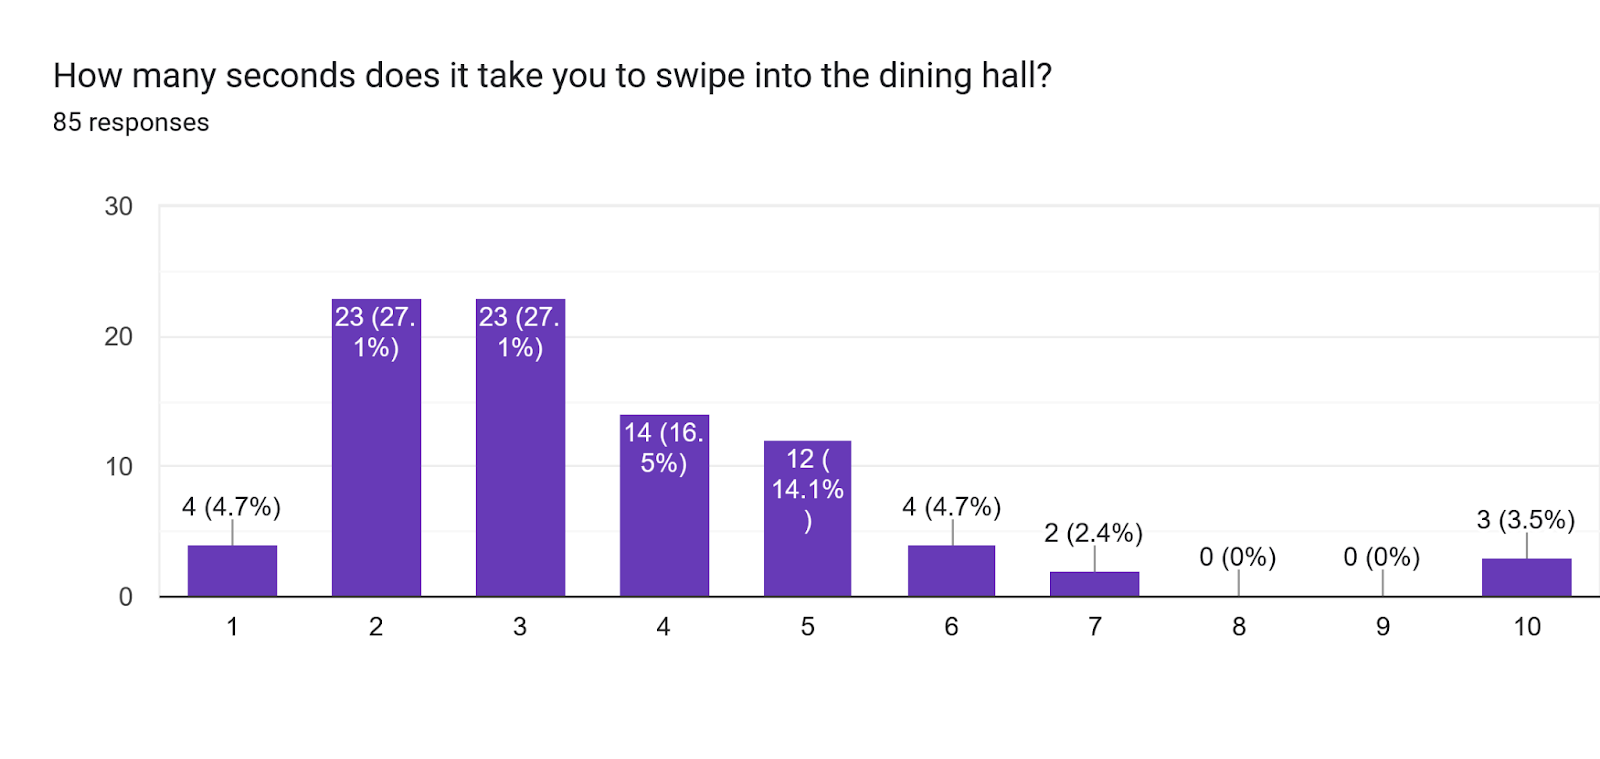

*Fig 2. Responses of Olin students on the question: “How many seconds does it take you to wipe into the dining hall?” With seconds on the x-axis and response frequency on the y-axis.*

With this, we observed that 2-5 seconds are the most frequent times, and made the assumption that all students would swipe in with an equal probability, which we modelled as a uniform beta distribution. This does make our model slightly less accurate, however, qualitatively the dining hall swipe in times will not be the most significant bottleneck, so the small amount of error is mostly irrelevant. This distribution is a random variable in our model.

We also collected data on the frequency that Olin students went to the four different stations for food.

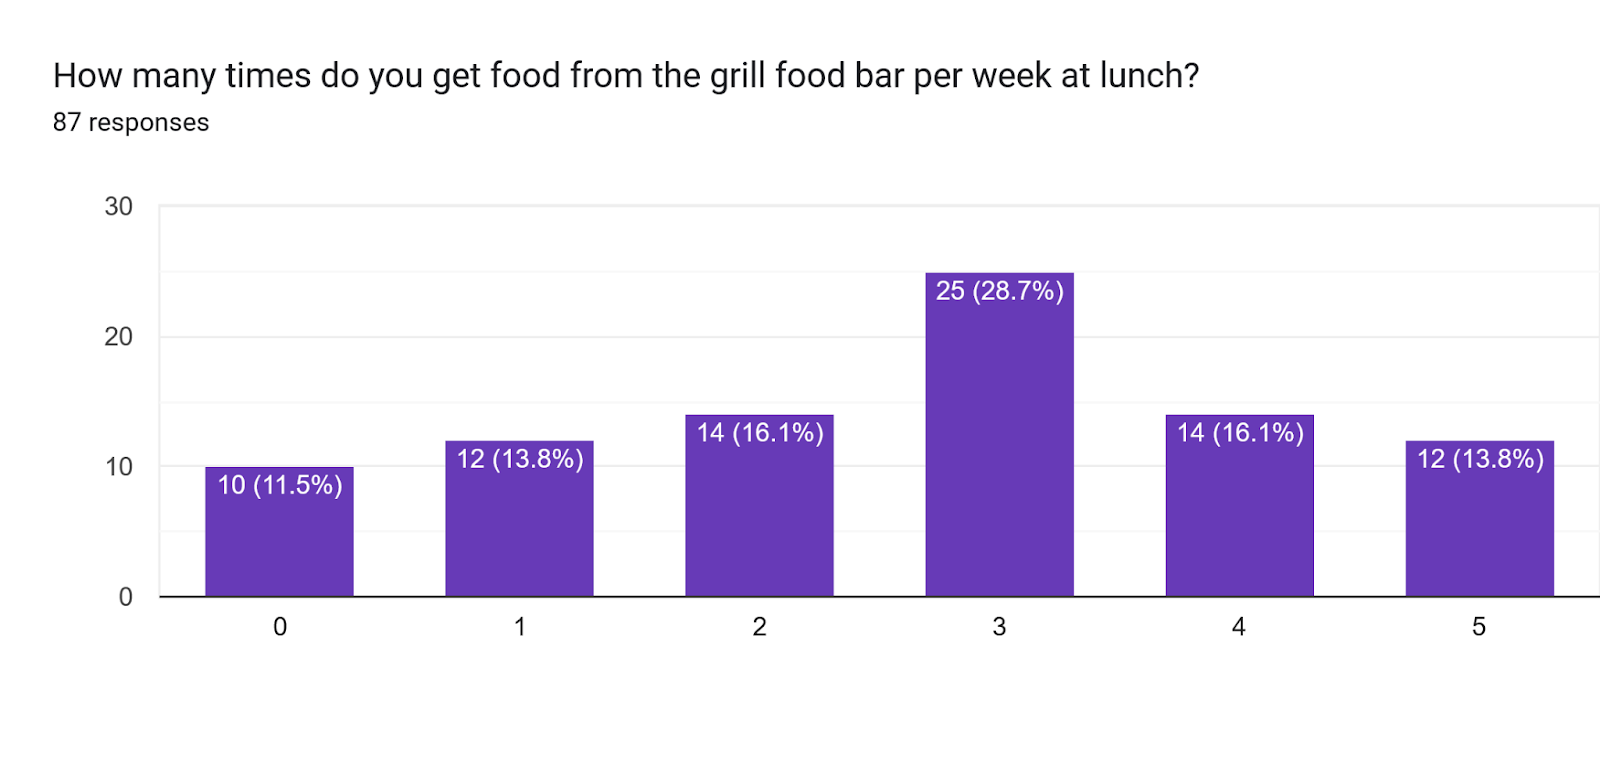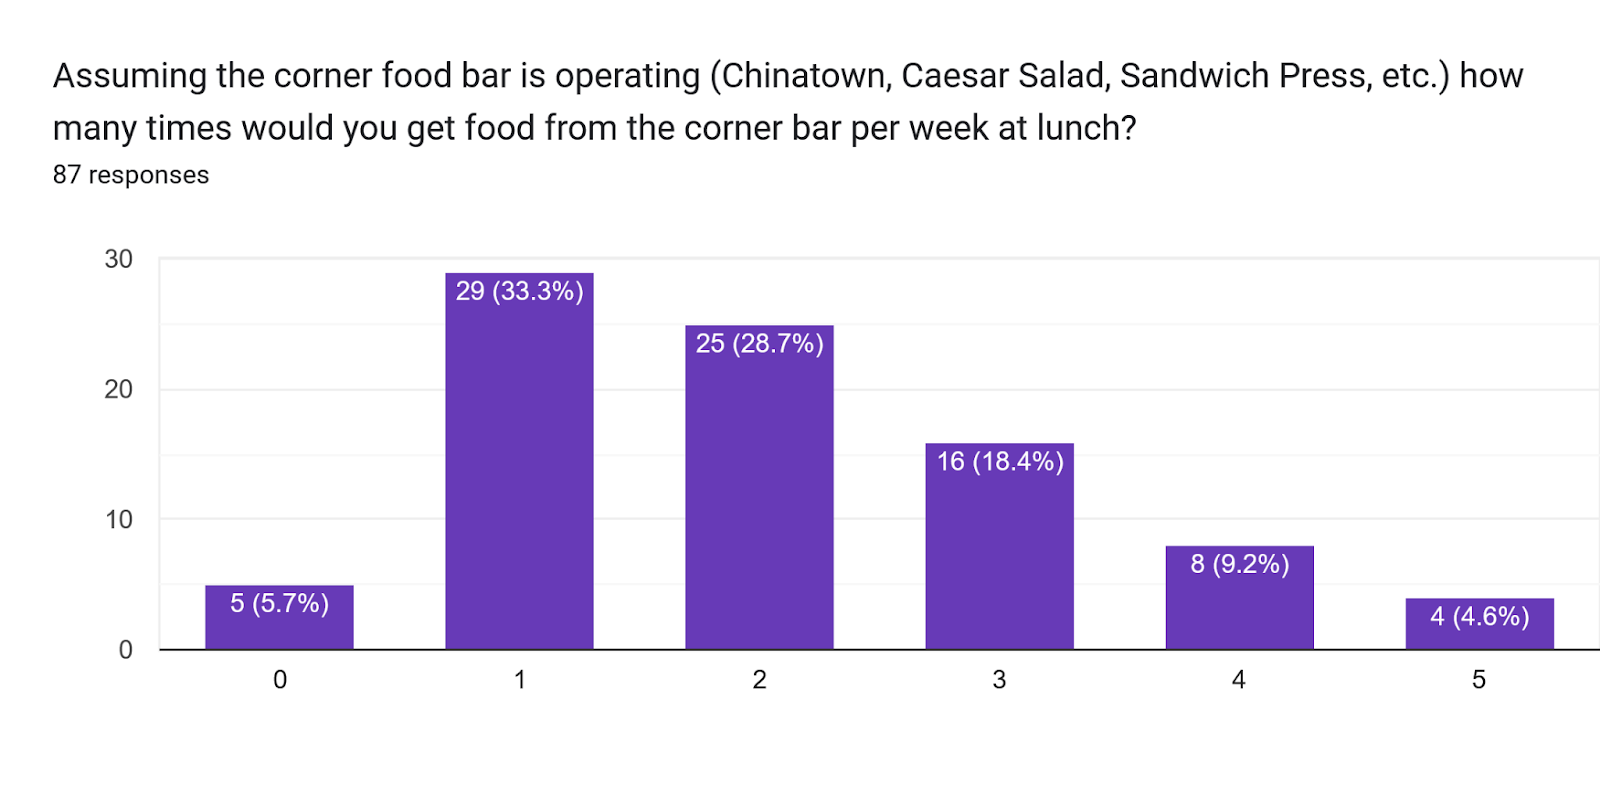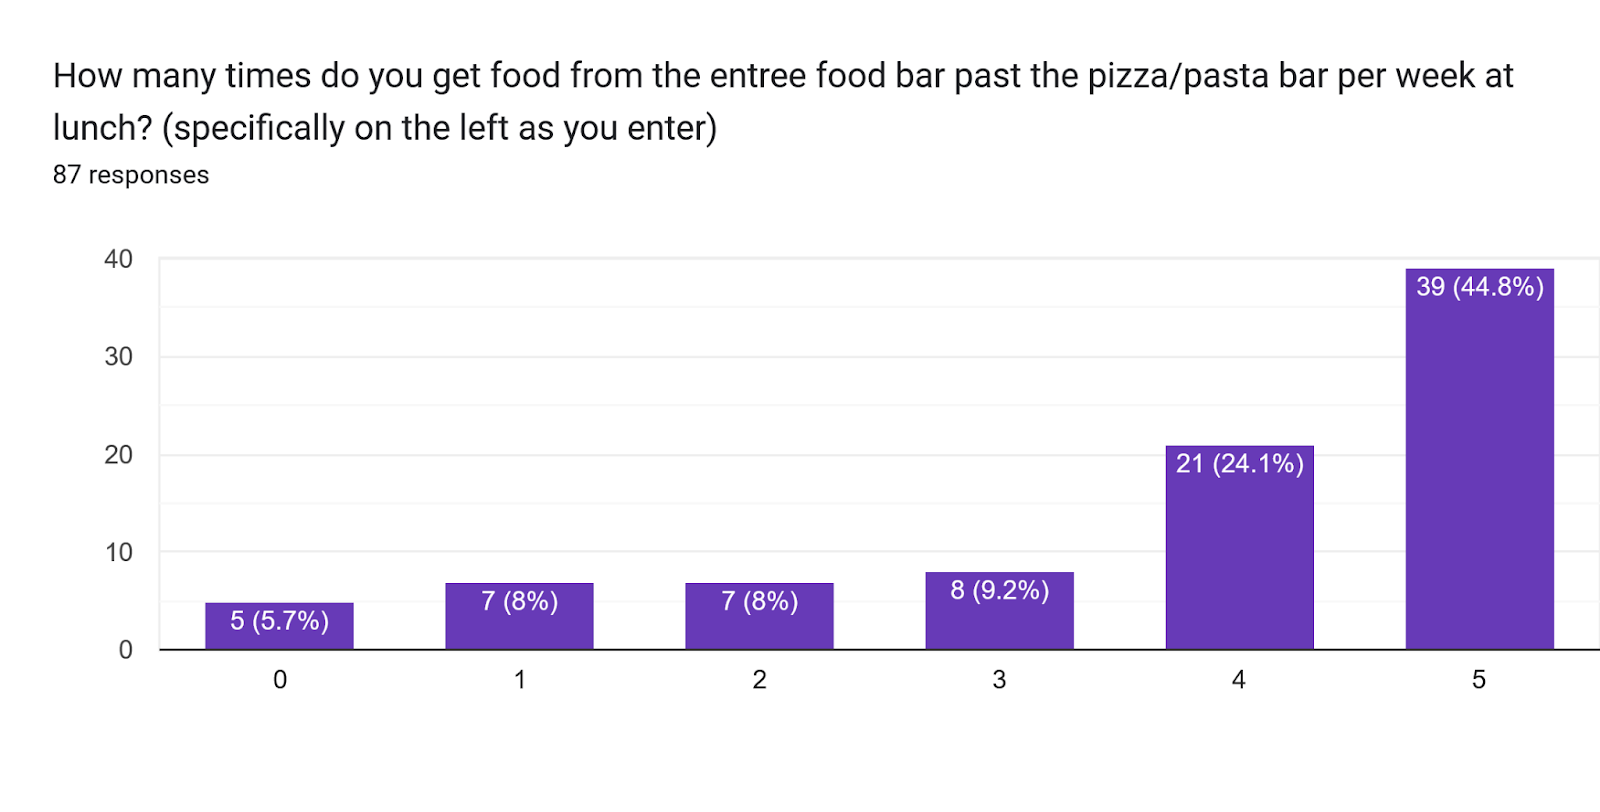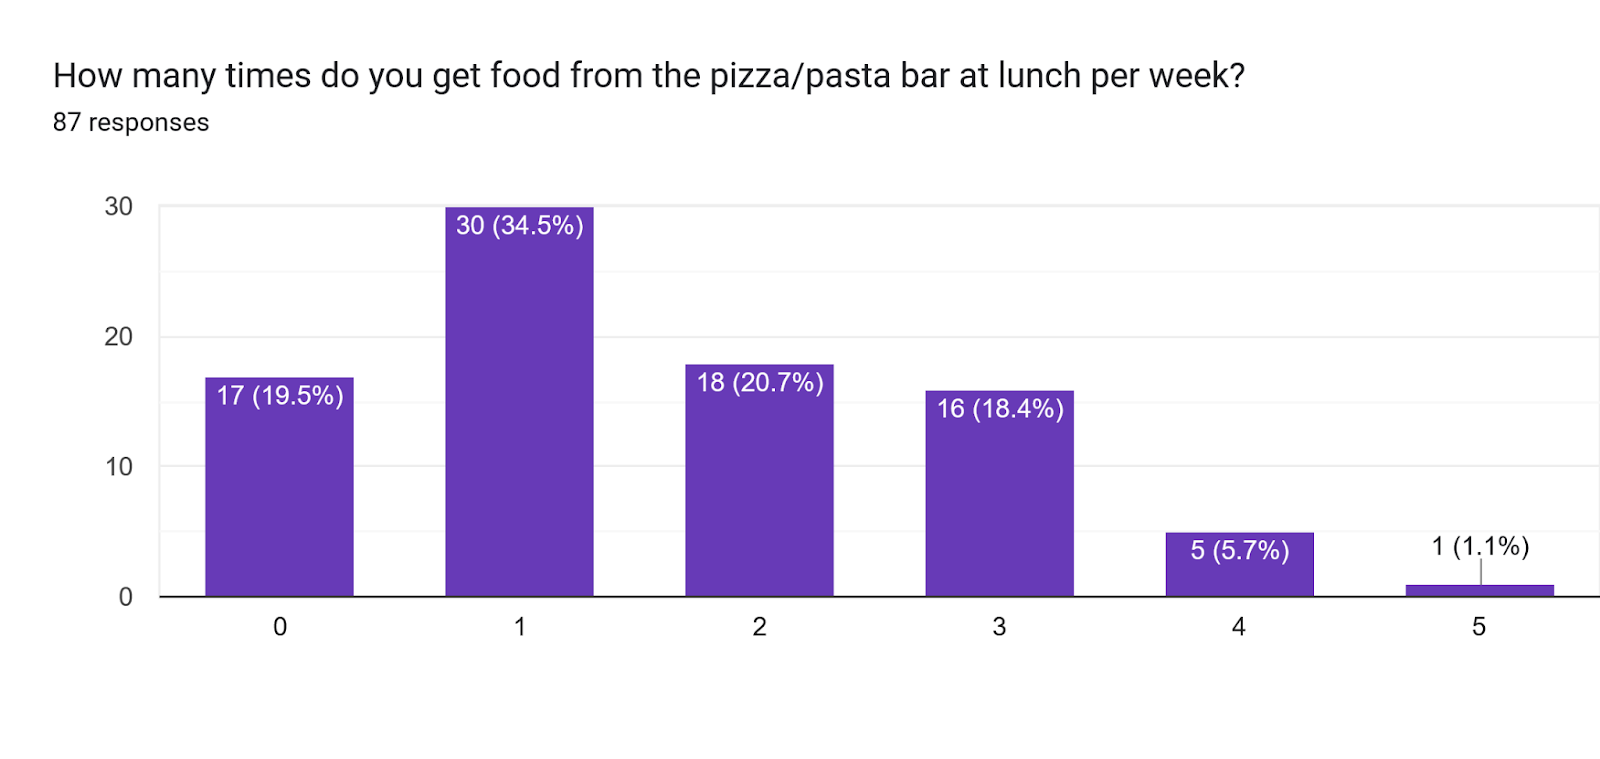

*Fig 3. Responses of Olin students on questions of how many times they go to each dining hall station per week for lunch, with number of times on the x-axis and response frequency on the y-axis. *

## **The Model**

**Description:**

The closest modeling technique for a problem like this is to use a system similar to Markov chains. Markov chains are probabilistic, state-based models, in which each state has unique properties for how stocks will flow through it. In terms of queueing, Markov chains have been used to model supply chains, however it is still applicable to our model (Mengfei Chen et al., 2025). We have decided to model the Olin dining hall as a modified, agent-based, system of Markov chains, in which we have a limited calling population moving through a complex system.

This model resulted in the following Tenchi diagram:

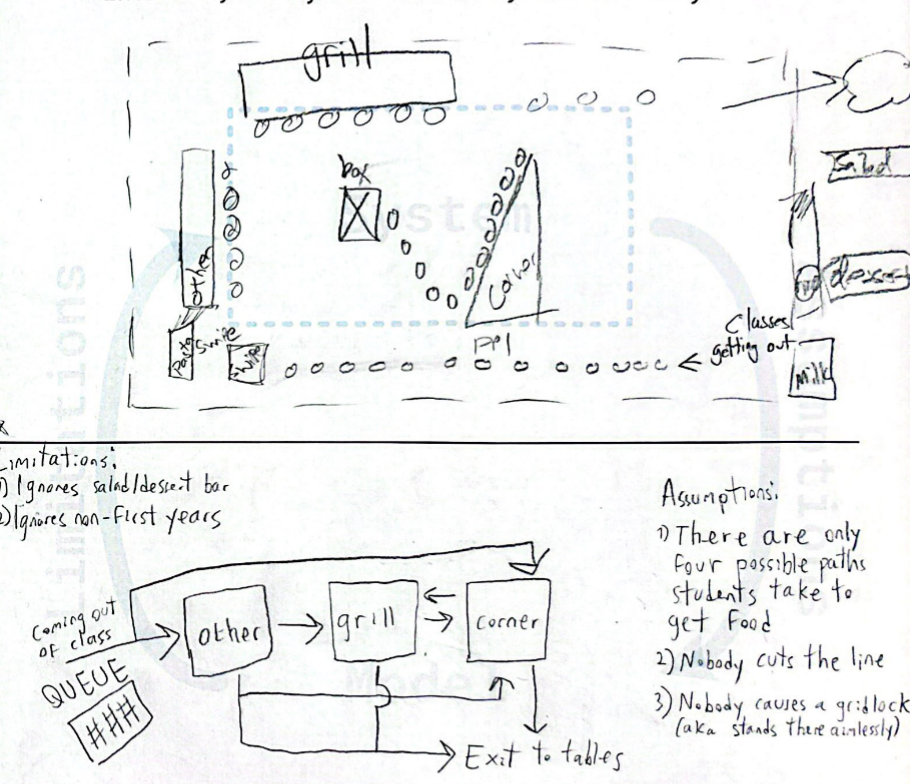

*Fig 4. Tenchi Diagram for our research question, specifically the queue of the Olin dining hall.*

Which results into the following update equations (actual code achieves this using time steps, this is simplified):


$$S_{i-1} \;\left(\textrm{previous}\;\textrm{station}\;\textrm{or}\;\textrm{checkin}\right)\to \textrm{student}\to S_{i\;} \;\left(\textrm{next}\;\textrm{station}\right)$$



$$\textrm{student}\;\textrm{does}\;\textrm{not}\;\textrm{move}\;\textrm{unless}\;S_i \;\textrm{is}\;\textrm{not}\;\textrm{full}$$



$$S_{i-1} \to \textrm{student}\to \textrm{EXIT}$$



$$\textrm{student},\textrm{once}\;\textrm{path}\;\textrm{is}\;\textrm{complete}\;\textrm{and}\;\textrm{visited}\;\textrm{all}\;\textrm{target}\;\textrm{stations},\textrm{exits}\;\textrm{out}\;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{and}\;\textrm{is}\;\textrm{no}\;\textrm{longer}\;\textrm{considered}$$


One key assumption of this model is that every student would follow the structure of the line. Technically, in the physical world, people could go straight to the grill, however we initially determined that would be an unusual path. As such, we have modeled more typical paths, in which at any point students can go to the corner station, however they must go from the pasta bar to the entree bar to the grill, and cannot between those stations, which maps physically to the structure of the dining hall.

clearvars; close all; clc;

%% ---------------- Parameters ----------------
N = 100;                % number of students
simT = 10000;           % simulation horizon in seconds
dt = 1;                 % sampling interval for queue time-series (s)
arrival_jitter_split = 600;   % 10 minutes
arrival_jitter_all12 = 100;   % ~1 student / second for 100 students

trials = 100;           % Number of trials

% Class end times (seconds since 10:00AM)
t_10_20 = 20*60;        % 1200 s
t_12_00 = 120*60;       % 7200 s

% Check-in service distribution (uniform)
checkin_min = 2;
checkin_max = 5;

% Check that number of students is positive
assert(N > 0, 'Number of students N must be greater than zero.');
% Check that simulation time is positive
assert(simT > 0, 'Simulation time (simT) must be greater than zero.');
% Check for valid sampling interval
assert(dt > 0, 'Sampling interval (dt) must be positive.');
% Check arrival jitter for valid positive values
assert(arrival_jitter_split > 0, 'Arrival jitter split must be positive.');
assert(arrival_jitter_all12 > 0, 'Arrival jitter for all12 scenario must be positive.');
% Check number of trials
assert(trials > 0, 'Number of trials must be positive.');
% Validate check-in service times
assert(checkin_min > 0 && checkin_max > 0 && checkin_min < checkin_max, ...
    'Check-in service times must be positive, and min time should be less than max time.');

Development:

We then needed to convert our research to usable data for a group of people. To do this, we found the mean popularity of each station, and created the probabilities that any given person would want to go to that station. The probabilities are as follows:

P_pizza   = 0.3232;

P_entree  = 0.7448;

P_grill   = 0.5310;

P_corner  = 0.4115

From these histograms, we generate a list of 100 students, each with four values representing the probability that they go to a given station. The creation of the people is also random. If any student chooses to go to a station, they will take a deterministic amount of time depending on the station. If they do not want food from a station, but are stuck in that line, they will wait until they can move through the line to the station they want to be with, but will not necessarily stop if no one is in front of them. If a student wants food from a station, the time it takes for them to get food values are as follows:

T_pizza = 10

T_entree = 10

T_grill = 10

T_corner = 30

The times are all fairly short, except the corner station, which often has a dining hall employee making a custom order. These values are measured off of qualitative estimations of each station.

Another deterministic value is the size of each station. We observed that all dining hall stations accomodate approximately 6 people, except the corner station, which typically can accomodate more people.

S_pizza = 6

S_entree = 6

S_grill = 6

S_corner = 8

% Station capacities
capacity.P = 6;
capacity.E = 6;
capacity.G = 6;
capacity.C = 8;

% Station deterministic service times (s)
tP = 10; tE = 10; tG = 10; tC = 30;

% Food choice probabilities
P_pizza   = 0.3232;
P_entree  = 0.7448;
P_grill   = 0.5310;
P_corner  = 0.4115;

% Path probabilities (PEGC, PEG, PEC, PE)
P_PEGC = P_pizza * P_entree * P_grill * P_corner;
P_PEG = P_pizza * P_entree * P_grill;
P_PEC = P_pizza * P_entree * P_corner;
P_PE = P_pizza * P_entree;

total_prob = P_PEGC + P_PEG + P_PEC + P_PE;

P_PEGC_normalized = P_PEGC / total_prob;
P_PEG_normalized = P_PEG / total_prob;
P_PEC_normalized = P_PEC / total_prob;
P_PE_normalized = P_PE / total_prob;

path_probs = [P_PEGC_normalized, P_PEG_normalized, P_PEC_normalized, P_PE_normalized];

% Travel times between nodes
tt_checkin_to_station.P = 1; tt_checkin_to_station.E = 2;
tt_checkin_to_station.G = 3; tt_checkin_to_station.C = 4;

tt_station_to_station.P.E = 1; tt_station_to_station.P.G = 1; tt_station_to_station.P.C = 1;
tt_station_to_station.E.G = 1; tt_station_to_station.E.C = 1;
tt_station_to_station.G.C = 1;

% Output folder
logfolder = pwd;

%% Validate
if abs(sum(path_probs)-1) > 1e-12
    error('path_probs must sum to 1');
end

%% Scenarios
scenarios = {'split','all12'};
results = struct();

**Metrics and Sweeps:**

To best answer our modelling question, we chose to look at the metric of number of students arriving at once, one where two groups of 50 students arrive at different times, representing days where first years get out of QEA at two different times, and one where a single group of 100 students arrive at noon, representing days where DesNat gets out and all first years move to the dining hall at once. We are assuming that all 100 students all arrive at exactly the same time. This limits precision, but the general trends of a large body of students arriving as opposed to a smaller body will still be fairly accurate. In order to account for the randomness of the generation of students, we run 100 different simulations, and find an average result to get a best estimate of how the number of students affects the queue size.

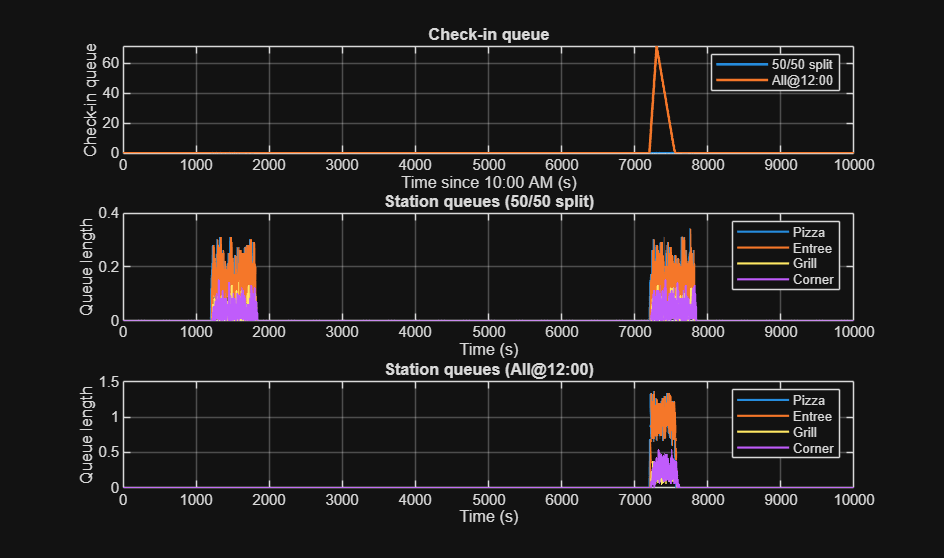

for sIdx = 1:numel(scenarios)
    scenario = scenarios{sIdx};
    %fprintf('\n=== Scenario: %s ===\n', scenario);

    times = 0:dt:simT;
    nTimes = numel(times);

    % storage across trials
    queue_ts_trials = zeros(trials, nTimes);
    station_queue_ts_trials = zeros(trials, 4, nTimes); % P,E,G,C
    trials_summary = cell(trials,1);

    for tr = 1:trials
        %fprintf(' Trial %d/%d ...\n', tr, trials);
        summary = struct();   % reset per trial

        % Generate arrivals and sample paths
        arrivals = generate_arrivals(N, scenario, ...
    t_10_20, t_12_00, arrival_jitter_split, arrival_jitter_all12);
        paths = sample_paths(N, path_probs);

        % Validate that paths sampled are within expected values (PEGC, PEG, PEC, PE)
        valid_paths = {'PEGC', 'PEG', 'PEC', 'PE'};
        assert(all(ismember(paths, valid_paths)), 'Some sampled paths are invalid.');

        % Run check-in
        station_next_free.P = 0;
        station_next_free.E = 0;
        station_next_free.G = 0;
        station_next_free.C = 0;

        [ci_start, ci_end, ci_wait] = run_checkin(arrivals, checkin_min, checkin_max);

        % Ensure that check-in start times are always after or equal to arrival times
        assert(all(ci_start >= arrivals), 'Check-in start times cannot be earlier than arrival times.');
        
        % Ensure that check-in end times are after check-in start times
        assert(all(ci_end >= ci_start), 'Check-in end times must be after check-in start times.');

        % -------------------- Station simulation with food choice --------------------
        [student_timeline, station_records, station_queue_log] = ...
    simulate_stations( ...
        ci_end, paths, tP, tE, tG, tC, ...
        tt_checkin_to_station, tt_station_to_station, capacity);

        % Compute queue time-series
        q_checkin = compute_queue_ts(arrivals, ci_start, times); % waiting outside check-in
        qP = queue_ts_from_log(station_queue_log.P, times);
        qE = queue_ts_from_log(station_queue_log.E, times);
        qG = queue_ts_from_log(station_queue_log.G, times);
        qC = queue_ts_from_log(station_queue_log.C, times);

        % Store timeseries
        queue_ts_trials(tr,:) = q_checkin;
        station_queue_ts_trials(tr,1,:) = qP;
        station_queue_ts_trials(tr,2,:) = qE;
        station_queue_ts_trials(tr,3,:) = qG;
        station_queue_ts_trials(tr,4,:) = qC;

        % Summaries
        summary.avg_checkin_queue = mean(q_checkin);
        [summary.peak_checkin, idx_peak] = max(q_checkin);
        summary.peak_checkin_time = times(idx_peak);
        summary.avg_checkin_wait = mean(ci_wait);
        summary.pct_wait_over30 = mean(ci_wait > 30) * 100;
        trials_summary{tr} = summary;
    end

    % Aggregate results
    results.(scenario).times = times;
    results.(scenario).queue_ts_mean = mean(queue_ts_trials, 1);
    results.(scenario).station_queue_ts_mean = squeeze(mean(station_queue_ts_trials, 1));
    results.(scenario).trials_summary = trials_summary;
end

%% ---------------- Plot results ----------------
figure('Name','Check-in & Station queues','NumberTitle','off','Units','normalized','Position',[0.05 0.05 0.9 0.85]);
t = results.split.times;
subplot(3,1,1);
plot(t, results.split.queue_ts_mean, 'LineWidth', 1.5); hold on;
plot(t, results.all12.queue_ts_mean, 'LineWidth', 1.5);
xlabel('Time since 10:00 AM (s)'); ylabel('Check-in queue');
legend('50/50 split','All@12:00'); grid on; title('Check-in queue');

subplot(3,1,2);
plot(t, results.split.station_queue_ts_mean(1,:), 'LineWidth', 1.2); hold on;
plot(t, results.split.station_queue_ts_mean(2,:), 'LineWidth', 1.2);
plot(t, results.split.station_queue_ts_mean(3,:), 'LineWidth', 1.2);
plot(t, results.split.station_queue_ts_mean(4,:), 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Queue length');
legend('Pizza','Entree','Grill','Corner'); grid on; title('Station queues (50/50 split)');

subplot(3,1,3);
plot(t, results.all12.station_queue_ts_mean(1,:), 'LineWidth', 1.2); hold on;
plot(t, results.all12.station_queue_ts_mean(2,:), 'LineWidth', 1.2);
plot(t, results.all12.station_queue_ts_mean(3,:), 'LineWidth', 1.2);
plot(t, results.all12.station_queue_ts_mean(4,:), 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Queue length');
legend('Pizza','Entree','Grill','Corner'); grid on; title('Station queues (All@12:00)');

## **The Results**

**Analysis:**

Our results have very two very low mean averages for the station queues. This is because at any given point in the line, it seems likely that one person would be at a station, and many people behind them would be waiting, but not want food from that station. This would result in a cascade effect when that person finishes getting there food which is upredictable across different trials. As such, our analysis of station queue lengths are strictly comparitive. 

Our first condition, being 50 students at two different points in time, resulted in relatively low maximum check in queue lengths. Totalling typically at most 2 people in the check-in queue, an average of 0.15 people at the pizza and entree station queues, and an average of 0.04 people at the grill and corner station queues. Our second condition, with 100 students all at once, resulted in far greater maximum queue sizes. With a maximum initial queue of 70, a pizza and entree station queue averaging 1, a corner station queue of 0.3, and a grill station queue of 0.15. This shows how only doubling the number of students enormously impacts the check-in queue length, and changes the station queue lengths by up to a factor of 6 for the earlier stations, or a factor of three for the later stations.

## The Interpretation / Discussion

Therefore, we can see that the dining hall queueing structure is greatly affected by what time the first year’s morning classes get out, with all of the students getting out at once significantly increasing the queue size. The variety of desires of different stations, and the mostly linear nature of the queue, lead to most stations being occupied by only one or two people, when in fact many people are stuck behind others at stations they don’t even want to get food from. 

**Limitations and Further Work:**

An interesting limitation that we did not initially think would be significant is that skipping the line in the Olin dining hall is sometimes encouraged. Based on empirical observation, we believed that skipping the queue was only a marginal action at Olin, however, the number of people stuck in the queue may imply that skipping is actually a very important aspect of the lunch line at Olin, and is encouraged for a very important reason.

Additional research could be conducted that examines the culture of cutting the line in the dining hall, the rate at which students engage in that behavior, and how it affects the queue size. Our model cannot account for skipping, and only enables cutting for certain stations, like moving to the corner bar, or leaving the line early, when in reality, students can move directly to the grill after swiping in, if they only want food from that station.


%% ---------------- Helper functions (the code references these throughout) ----------------
function arrivals = generate_arrivals(N, scenario, t1, t2, jitter_split, jitter_all12)
    switch scenario
        case 'split'
            n1 = floor(N/2);
            n2 = N - n1;
            a1 = t1 + rand(n1,1) * jitter_split;
            a2 = t2 + rand(n2,1) * jitter_split;
            arrivals = sort([a1; a2]);

        case 'all12'
            arrivals = sort(t2 + rand(N,1) * jitter_all12);

        otherwise
            error('Unknown scenario');
    end
end

function paths = sample_paths(N, probs)
    edges_cum = cumsum(probs(:)');
    r = rand(N,1);
    paths = cell(N,1);
    for i = 1:N
        if r(i) <= edges_cum(1)
            paths{i} = 'PEGC';
        elseif r(i) <= edges_cum(2)
            paths{i} = 'PEG';
        elseif r(i) <= edges_cum(3)
            paths{i} = 'PEC';
        else
            paths{i} = 'PE';
        end
    end
end

function [start_times, end_times, wait_times] = run_checkin(arrivals, smin, smax)
    N = numel(arrivals);
    start_times = zeros(N,1);
    end_times   = zeros(N,1);
    wait_times  = zeros(N,1);
    next_free = 0;

    for i = 1:N
        sstart = max(arrivals(i), next_free);
        service = smin + (smax - smin)*rand();
        send = sstart + service;

        start_times(i) = sstart;
        end_times(i)   = send;
        wait_times(i)  = sstart - arrivals(i);

        next_free = send;
    end
end

%% ---------------- Station simulation ----------------
function [student_timeline, station_records, station_queue_log] = ...
    simulate_stations(checkin_end, paths, tP, tE, tG, tC, ...
                      tt_ci, tt_ss, capacity)
    stations = {'P','E','G','C'};
    dwell = struct('P',tP,'E',tE,'G',tG,'C',tC);
    
    % Track when each spot in the station becomes free
    release_times = struct('P',[],'E',[],'G',[],'C',[]);

    % Ensure that the station release times are handled properly
assert(all(structfun(@(x) isempty(x) || all(x >= 0), release_times)), ...
    'Station release times must be non-negative.');
    
    % Initialize logs
    for s = stations
        station_records.(s{1}).arrivals = [];
        station_records.(s{1}).starts   = [];
        station_queue_log.(s{1}).time   = [];
        station_queue_log.(s{1}).qlen   = [];
    end
    
    N = numel(checkin_end);
    student_timeline = cell(N,1);
    [~, order] = sort(checkin_end);
    
    % ---------------- Simulation ----------------
    for k = 1:N
        i = order(k);
        cur_t = checkin_end(i);
        last = '';
        st = struct();
        
        for j = 1:numel(paths{i})
            s = paths{i}(j);
            
            % ---- 1. Travel to Station ----
            if isempty(last)
                t_arr = cur_t + tt_ci.(s);
            else
                t_arr = cur_t + tt_ss.(last).(s);
            end
            
            % ---- 2. Wait for physical space ----
            % Remove people who left BEFORE I arrived
            release_times.(s)(release_times.(s) <= t_arr) = [];
            
            % If still full, wait for the next person to leave
            while numel(release_times.(s)) >= capacity.(s)
                t_arr = min(release_times.(s)); % Jump time to when a spot opens
                release_times.(s)(release_times.(s) <= t_arr) = []; % Clear that spot
            end
            
            % ---- 3. Enter station ----
            s_start = t_arr;
            s_end_tentative = s_start + dwell.(s);
            
            % ---- 4. Blocking / Next Station Check ----
            % Before we can finish here, check if we are blocked by the next station
            if j < numel(paths{i})
                next = paths{i}(j+1);
                t_reach_next = s_end_tentative + tt_ss.(s).(next);
                
                % Check how many people are in 'next' at the time we would arrive
                % (Count timestamps in 'next' that are still in the future relative to t_reach_next)
                active_in_next = sum(release_times.(next) > t_reach_next);
                
                while active_in_next >= capacity.(next)
                    % Next station is full. We are blocked.
                    % Find the earliest time a spot opens in 'next' AFTER our arrival
                    future_releases = sort(release_times.(next));
                    blockers = future_releases(future_releases > t_reach_next);
                    
                    if isempty(blockers)
                        break; % Should not happen given while condition, failsafe
                    end
                    
                    t_unblocked = min(blockers);
                    
                    % We extend our stay in CURRENT station 's'
                    extra_wait = t_unblocked - t_reach_next;
                    s_end_tentative = s_end_tentative + extra_wait;
                    
                    % Update time check for next iteration of while loop
                    t_reach_next = t_unblocked;
                    active_in_next = sum(release_times.(next) > t_reach_next);
                end
            end
            
            % ---- 5. Finalize and Log ----
            s_end = s_end_tentative;
            
            % Add my exit time to this station's release registry
            release_times.(s) = [release_times.(s), s_end];
            
            % Update logs
            station_records.(s).arrivals(end+1) = t_arr;
            station_records.(s).starts(end+1)   = s_start;
            
            % Log queue: count people currently in release_times (including me)
            current_q_len = numel(release_times.(s));
            station_queue_log.(s).time(end+1)   = t_arr;
            station_queue_log.(s).qlen(end+1)   = current_q_len;
            
            st.(s) = [s_start s_end];
            cur_t = s_end;
            last = s;
        end
        student_timeline{i} = st;
    end
end

%% ---------------- Queue timeseries ----------------
function q = compute_queue_ts(arrivals, service_starts, times)
    arrivals_sorted = sort(arrivals(:));
    starts_sorted = sort(service_starts(:));
    nTimes = numel(times);
    q = zeros(1, nTimes);
    ia = 1; isv = 1;
    nA = numel(arrivals_sorted); nS = numel(starts_sorted);
    for k = 1:nTimes
        t = times(k);
        while ia <= nA && arrivals_sorted(ia) <= t
            ia = ia + 1;
        end
        a_count = ia - 1;
        while isv <= nS && starts_sorted(isv) <= t
            isv = isv + 1;
        end
        s_count = isv - 1;
        q(k) = max(0, a_count - s_count);
    end
end

function q = queue_ts_from_log(log, times)
    q = zeros(size(times));
    idx = 1;

    for k = 1:numel(times)
        while idx <= numel(log.time) && log.time(idx) <= times(k)
            q(k) = log.qlen(idx);
            idx = idx + 1;
        end
    end
end